# Datos Thing Speak

% Definir la URL del canal ThingSpeak con la clave de lectura y el límite de resultados
url = 'https://api.thingspeak.com/channels/2746417/feeds.json?api_key=09KFL869WPOHHVVH&results=100';

% Leer los datos desde ThingSpeak
data = webread(url);

% Extraer los datos de inclinación en X y Y
feeds = data.feeds;  
inclinacionX = [];  
inclinacionY = [];  

for i = 1:numel(feeds)
    inclinacionX(i) = str2double(feeds(i).field1);  % Convierte el campo 1 a número y lo almacena
    inclinacionY(i) = str2double(feeds(i).field2);  % Convierte el campo 2 a número y lo almacena
end

% Guardar los datos en un archivo .mat
save('datos_inclinacion.mat', 'inclinacionX', 'inclinacionY');

% Visualizar los datos
disp('Datos de inclinación en X:');

Datos de inclinación en X:


disp(inclinacionX);

   26.4900   26.6500    7.3400   33.2800    6.5600  -20.3900   13.6900   13.0500    6.1400    7.3700    6.3100    5.4600    4.7800    1.9200    3.4500   51.4300  -17.8900    4.7200    4.7300    3.4100    5.5300    3.0500    3.3600    2.1700    2.0000    2.7300    3.1500    5.5500   -2.6500   -2.5900   -4.3000   -1.2200    2.0200   -4.5800   -3.8700  -48.9200   -0.8700    3.5700    4.0400    3.9500    4.8000    4.8600    4.7900    5.0600    5.4700    9.2700    4.2700    3.7400    3.1700    7.0800    7.2100    4.2300    5.2200    3.3100    3.3000    4.0200    2.8300    5.9200    6.3200    6.8700    6.6000    6.9200    3.7500    6.9300    7.1000    7.7100    7.3000    7.4700    7.3600    8.1200    7.9200    7.0500    6.8000    7.7700    7.6800    7.6500    7.3100    7.0900    7.2200    7.2200    7.5000    7.4200   71.8400   29.7500



disp('Datos de inclinación en Y:');

Datos de inclinación en Y:


disp(inclinacionY);

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  -37.8200  -37.4800  -37.9300  -40.2800  -28.1400  -32.0500  -65.2200  -64.7900  -64.2900  -65.1800  -64.6500  -64.9900  -65.5900  -64.0000  -64.9700  -63.4000  -64.3500  -65.7600  -65.7500  -64.7000  -63.8900  -65.7400  -65.6900  -69.0500  -66.1800  -66.3400  -68.8400  -65.5300  -64.9300  -64.6200  -64.0700  -64.6800  -60.8300  -64.8100  -65.0000  -63.7400  -64.8000  -64.5200  -65.0700  -64.4900  -64.6400  -64.9500  -65.4200  -64.6000  -64.9400  -64.7700  -64.9800  -64.9700  -64.6700  -64.7900  -64.7100  -64.9700  -17.5500  -56.2200



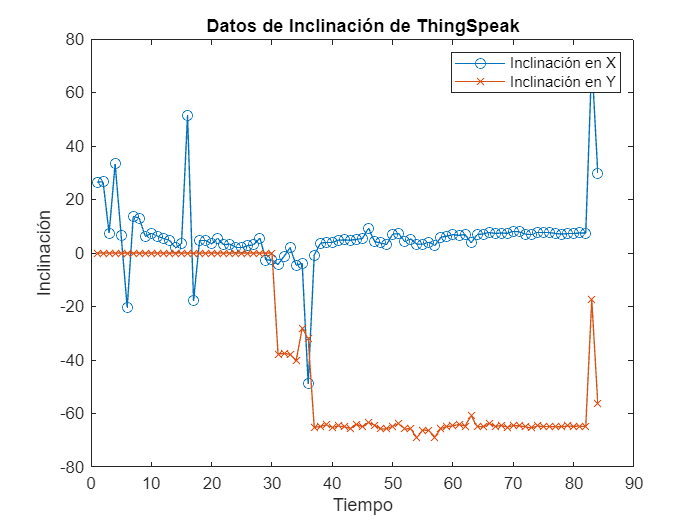


% Gráfica de los datos
figure;
plot(inclinacionX, '-o');
hold on;
plot(inclinacionY, '-x');
legend('Inclinación en X', 'Inclinación en Y');
xlabel('Tiempo');
ylabel('Inclinación');
title('Datos de Inclinación de ThingSpeak');
hold off;